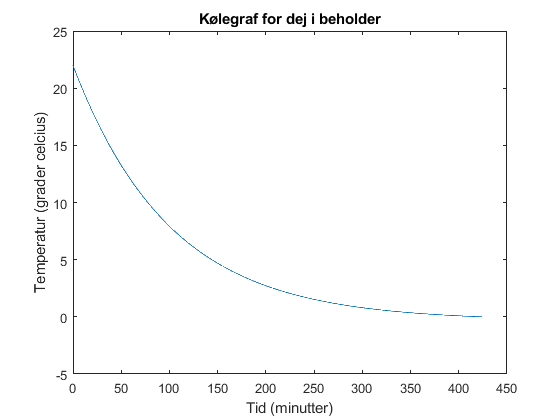

%%
W_peltier=23.22;    %Effekt fra peltier element i watt
T_luft=22;          %Luftens temperatur i celsius
T_target=0;        %Ønsket temperatur i celsius
k_PETG=0.29;        %Varmeledningsevne for beholder materiale
k_pla = 0.13;
k_luft = 0.024;
infill = 1;
k_tot = k_pla*infill + (1-infill)*k_luft;
m_dej=1.5;            %Masse af dej i kg

%Varmekapcitet for vand/dej
Q_vand=4180;        
Q_dej=Q_vand;

%Beholder dimmensioner
b_tank=0.10;        
h_tank=0.15;
d_tank=0.10;
tank_wall=0.01;
OverfladeAreal=b_tank*h_tank*2+b_tank*d_tank*2+h_tank*d_tank*2;

%Dataopløsning
time_between_readings=1;

%Beregning af temperatur forløb
temp = T_luft;

i = 2; %Tællevariabel

while((temp(i-1) > T_target) && (i < 130000))
  temp = [temp temp(i-1)-(W_peltier*time_between_readings-(k_tot*OverfladeAreal*(T_luft-temp(i-1))/tank_wall)*time_between_readings)/(Q_dej*m_dej)];
  i = i + 1;
end

%Minut akse
t = 0:(1*time_between_readings)/60:((length(temp)-1)*time_between_readings)/60;

figure(1); clf;
plot(t,temp);
xlabel("Tid (minutter)");
ylabel("Temperatur (grader celcius)");
title("Kølegraf for dej i beholder");